# DFT sygnału harmonicznego

f1 = 100

f1 = 100

f1 = 125

f1 = 125

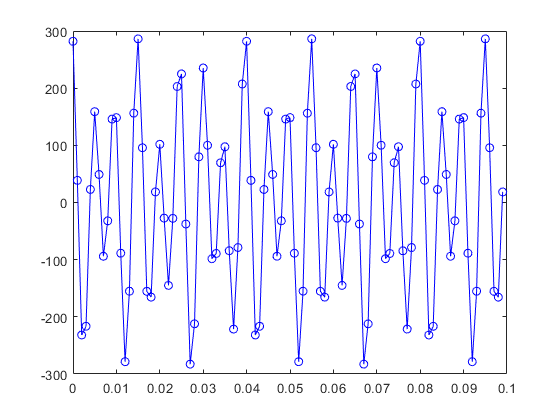

N = 100;


Agen = @(k,n) (1/sqrt(N))*(exp(1i*(2*pi)/N))^(-k*n);

A = zeros(N);
for n=1:N
    for k=1:N
        A(n,k)=Agen(n,k);
    end
end

fgen = @(t) 100*cos(2*pi*f1*t+pi/7) +  200*cos(2*pi*200*t+pi/11);


fs1000Hz = 1000;
x = fgen(0:1/fs1000Hz:(1/fs1000Hz*(N-1)));

clf
figure
plot(0:1/fs1000Hz:(1/fs1000Hz*(N-1)), x, 'b-o');

obliczanie DFT ze wzoru $X=\mathrm{Ax}$ 

X = A*x';

x_after = (A')*X;

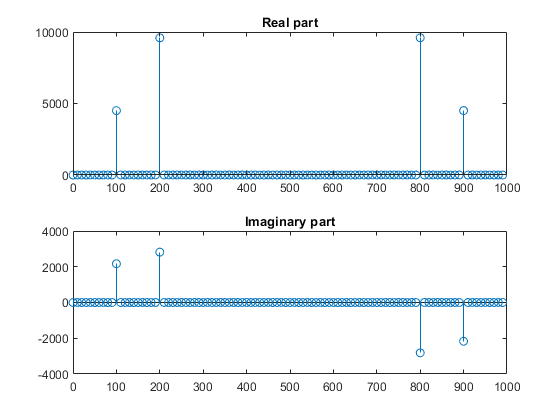

% DFT plots
clf
figure
subplot(2,1,1)
stem(fs1000Hz*(0:N-1)/N, real(X));
title("Real part")
subplot(2,1,2)
stem(fs1000Hz*(0:N-1)/N, imag(X));
title("Imaginary part")

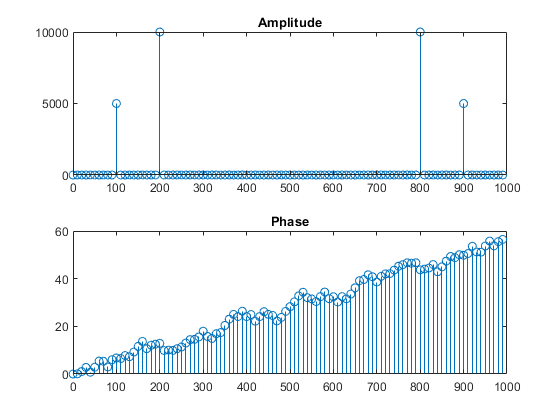


clf
figure
subplot(2,1,1)
stem(fs1000Hz*(0:N-1)/N, abs(X));
title("Amplitude")
subplot(2,1,2)
stem(fs1000Hz*(0:N-1)/N, unwrap(angle(X)));
title("Phase")

Rekonstrukcja

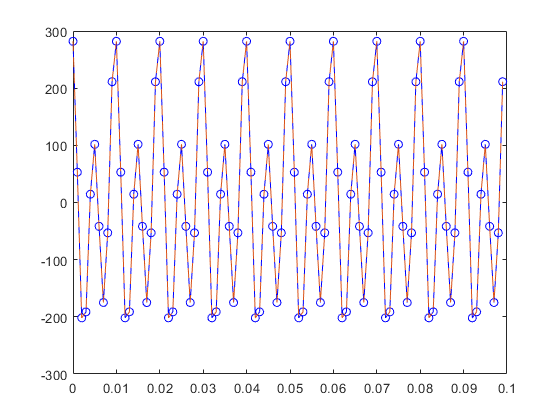

clf
figure
plot(0:1/fs1000Hz:(1/fs1000Hz*(N-1)), real(x_after), 'b-o');
hold on
plot(0:1/fs1000Hz:(1/fs1000Hz*(N-1)), x, '--')

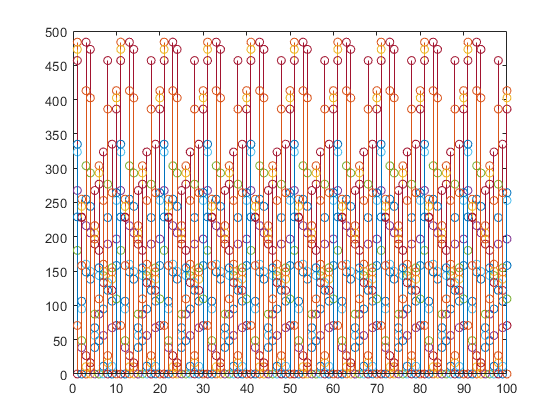


clf
figure
stem(abs(real(x_after)-x'))

Used fft():

X = fft(x);
x_after = ifft(X);

X_fft = X; x_after_fft = x_after;

Porownanie

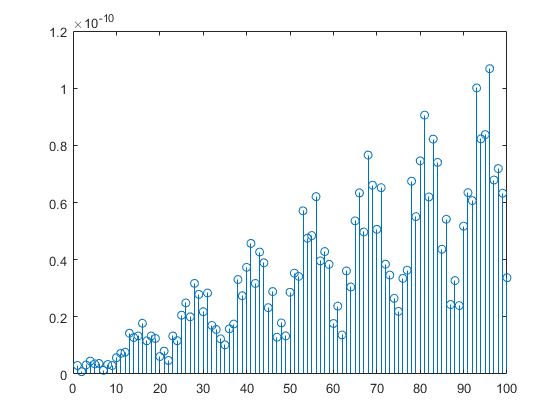

clf
figure
stem(abs(x_after_fft-x_after'))